**Phase responses**

- **Compute the response of (i) forward, (ii) reverse and (iii) forward-reverse filter for a simple Gaussian signal train. Match it with the input signal and see how response changes with mode of filtering. **

- **How can you perform a zero-phase filtering in this scenario?**

## Gaussian Pulse

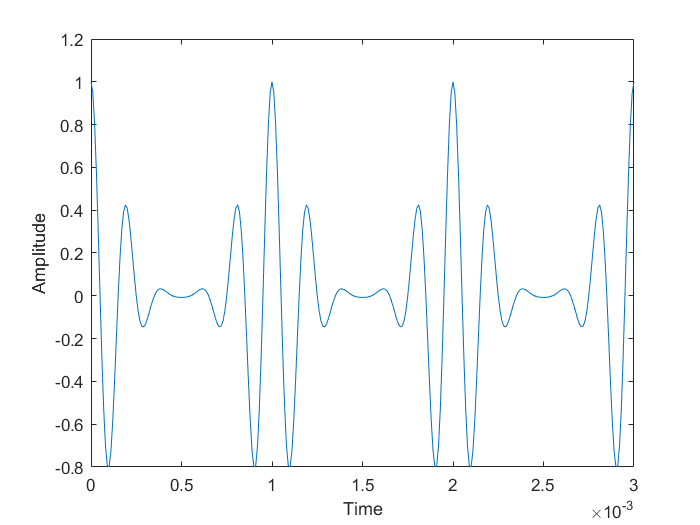

close all;
T = 0 : 1/100E3 : 3E-3;
D = [0 : 1/1E3 : 10E-3 ; 1.^(0:10)]';
Y = pulstran(T,D,@gauspuls,5E3,.5);
plot(T,Y)
xlabel ('Time');
ylabel ('Amplitude');

## Forward Filter

% BPF Design
close all
bpFilter = designfilt('bandpassfir', 'FilterOrder', 10, ...
             'CutoffFrequency1', 10E-3, 'CutoffFrequency2', 100E-3,...
             'SampleRate', 100E3)  % reducing the order of the filter = see change in am of signal

bpFilter =  digitalFilter with properties:

         Coefficients: [0.0146 0.0306 0.0726 0.1245 0.1665 0.1825 0.1665 0.1245 0.0726 0.0306 0.0146]

   Specifications:
    FrequencyResponse: 'bandpass'
      ImpulseResponse: 'fir'
           SampleRate: 100000
     CutoffFrequency1: 0.0100
     CutoffFrequency2: 0.1000
          FilterOrder: 10
         DesignMethod: 'window'

 Use fvtool to visualize filter
 Use designfilt to edit filter
 Use filter to filter data


filteredSignal = filter(bpFilter,Y)

filteredSignal =     0.0146    0.0445    0.1134    0.2263    0.3648    0.4912    0.5623    0.5453    0.4319    0.2428    0.0233   -0.2024   -0.3970   -0.5419   -0.6249   -0.6416   -0.5954   -0.4963   -0.3595   -0.2030   -0.0450    0.0979    0.2127    0.2912    0.3301    0.3311    0.2997    0.2445    0.1750    0.1010    0.0311   -0.0281   -0.0726   -0.1004   -0.1121   -0.1099   -0.0971   -0.0774   -0.0546   -0.0318   -0.0116    0.0045    0.0158    0.0224    0.0247    0.0237    0.0205    0.0160    0.0111    0.0064


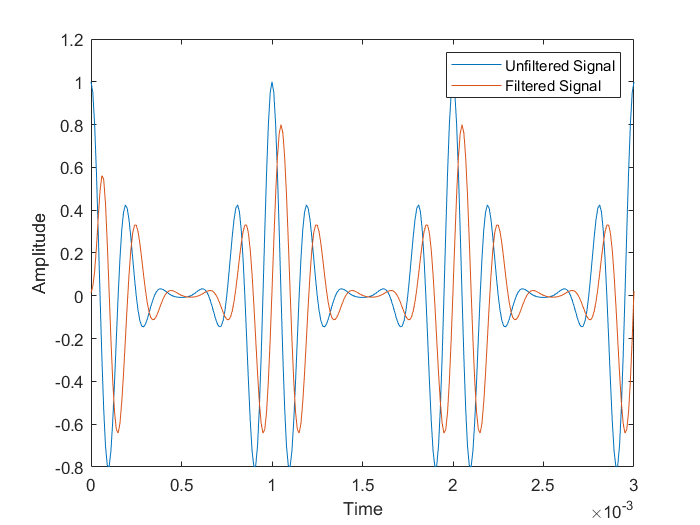

plot (T,Y);  hold on
plot (T,filteredSignal);
xlabel ('Time');
ylabel ('Amplitude');
legend ('Unfiltered Signal' , 'Filtered Signal')

Forward filtering adds a negative phase shift to the original signal

## Backward Filter

close all
bpFilter = designfilt('bandpassfir', 'FilterOrder', 10, ...
             'CutoffFrequency1', 10E-3, 'CutoffFrequency2', 100E-3,...
             'SampleRate', 100E3) 

bpFilter =  digitalFilter with properties:

         Coefficients: [0.0146 0.0306 0.0726 0.1245 0.1665 0.1825 0.1665 0.1245 0.0726 0.0306 0.0146]

   Specifications:
    FrequencyResponse: 'bandpass'
      ImpulseResponse: 'fir'
           SampleRate: 100000
     CutoffFrequency1: 0.0100
     CutoffFrequency2: 0.1000
          FilterOrder: 10
         DesignMethod: 'window'

 Use fvtool to visualize filter
 Use designfilt to edit filter
 Use filter to filter data


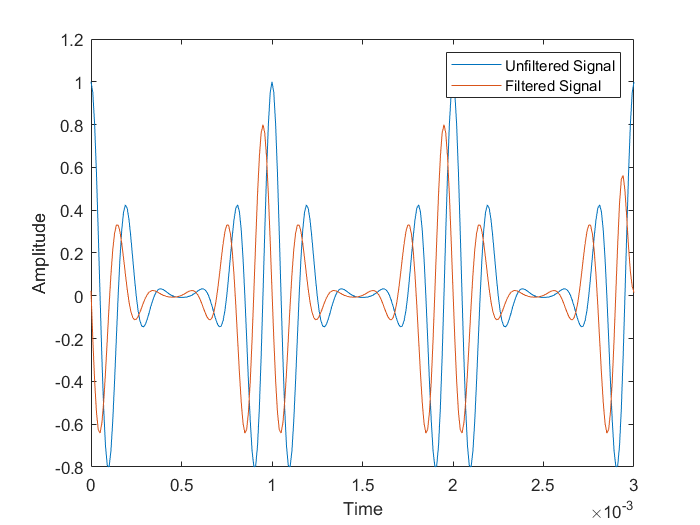

filteredSignal = filter(bpFilter,flip(Y));
filteredSignal = flip(filteredSignal);
plot (T,Y);  hold on
plot (T,filteredSignal);
xlabel ('Time');
ylabel ('Amplitude');
legend ('Unfiltered Signal' , 'Filtered Signal')

Backward filtering adds a positive phase shift to the original signal

## Forward Backward Filter

close all
bpFilter = designfilt('bandpassfir', 'FilterOrder', 10, ...
             'CutoffFrequency1', 10E-3, 'CutoffFrequency2', 100E-3,...
             'SampleRate', 100E3)  

bpFilter =  digitalFilter with properties:

         Coefficients: [0.0146 0.0306 0.0726 0.1245 0.1665 0.1825 0.1665 0.1245 0.0726 0.0306 0.0146]

   Specifications:
    FrequencyResponse: 'bandpass'
      ImpulseResponse: 'fir'
           SampleRate: 100000
     CutoffFrequency1: 0.0100
     CutoffFrequency2: 0.1000
          FilterOrder: 10
         DesignMethod: 'window'

 Use fvtool to visualize filter
 Use designfilt to edit filter
 Use filter to filter data


filteredSignal = filter(bpFilter,Y)  %forward

filteredSignal =     0.0146    0.0445    0.1134    0.2263    0.3648    0.4912    0.5623    0.5453    0.4319    0.2428    0.0233   -0.2024   -0.3970   -0.5419   -0.6249   -0.6416   -0.5954   -0.4963   -0.3595   -0.2030   -0.0450    0.0979    0.2127    0.2912    0.3301    0.3311    0.2997    0.2445    0.1750    0.1010    0.0311   -0.0281   -0.0726   -0.1004   -0.1121   -0.1099   -0.0971   -0.0774   -0.0546   -0.0318   -0.0116    0.0045    0.0158    0.0224    0.0247    0.0237    0.0205    0.0160    0.0111    0.0064


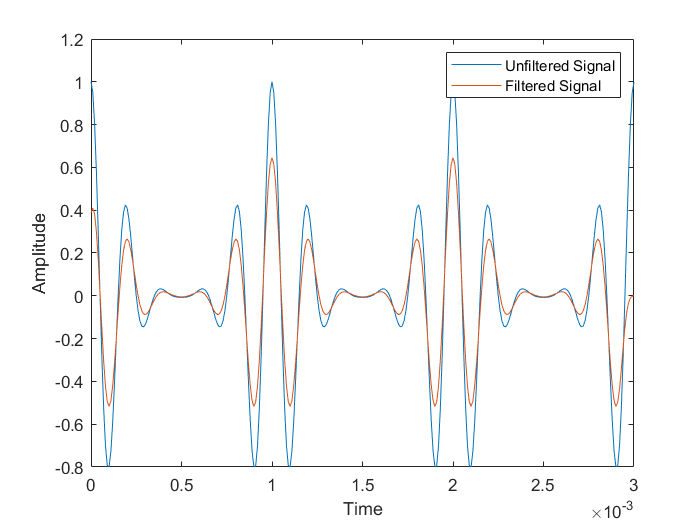

filteredSignal = filter(bpFilter,flip(filteredSignal));
filteredSignal = flip(filteredSignal);
plot (T,Y);  hold on
plot (T,filteredSignal);
xlabel ('Time');
ylabel ('Amplitude');
legend ('Unfiltered Signal' , 'Filtered Signal')

## Zero Phase Filtering

close all
bpFilter = designfilt('bandpassfir', 'FilterOrder', 10, ...
             'CutoffFrequency1', 10E-3, 'CutoffFrequency2', 100E-3,...
             'SampleRate', 100E3) 

bpFilter =  digitalFilter with properties:

         Coefficients: [0.0146 0.0306 0.0726 0.1245 0.1665 0.1825 0.1665 0.1245 0.0726 0.0306 0.0146]

   Specifications:
    FrequencyResponse: 'bandpass'
      ImpulseResponse: 'fir'
           SampleRate: 100000
     CutoffFrequency1: 0.0100
     CutoffFrequency2: 0.1000
          FilterOrder: 10
         DesignMethod: 'window'

 Use fvtool to visualize filter
 Use designfilt to edit filter
 Use filter to filter data


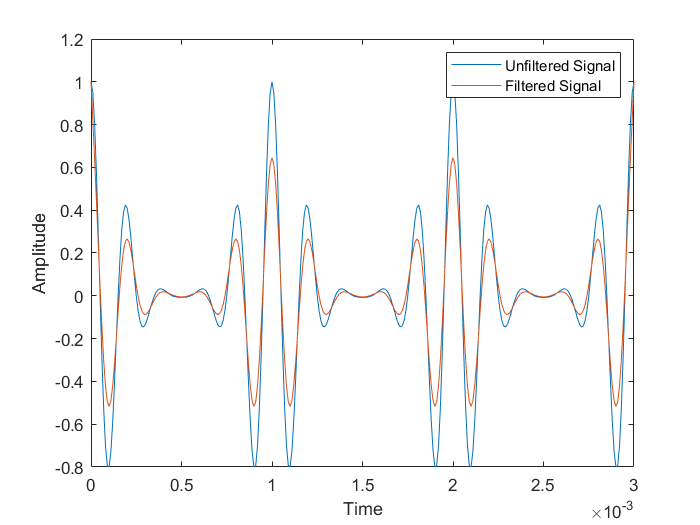

filteredSignal = filtfilt(bpFilter,Y);
plot (T,Y);  hold on
plot (T,filteredSignal);
xlabel ('Time');
ylabel ('Amplitude');
legend ('Unfiltered Signal' , 'Filtered Signal')